data = readmatrix('flightData.dat');
format long g
disp(data(1:750,:))

                         0                         0                         0
                         1                        12         0.224887556221889
                         2                        24         0.449775112443778
                         3                        36         0.674662668665667
                         4                        48         0.899550224887556
                         5                        60          1.12443778110945
                         6                        72          1.34932533733133
                         7                        84          1.57421289355322
                         8                        96          1.79910044977511
                         9                       108            2.023988005997
                        10                       120          2.24887556221889
                        11                       132          2.47376311844078
                        12                       144

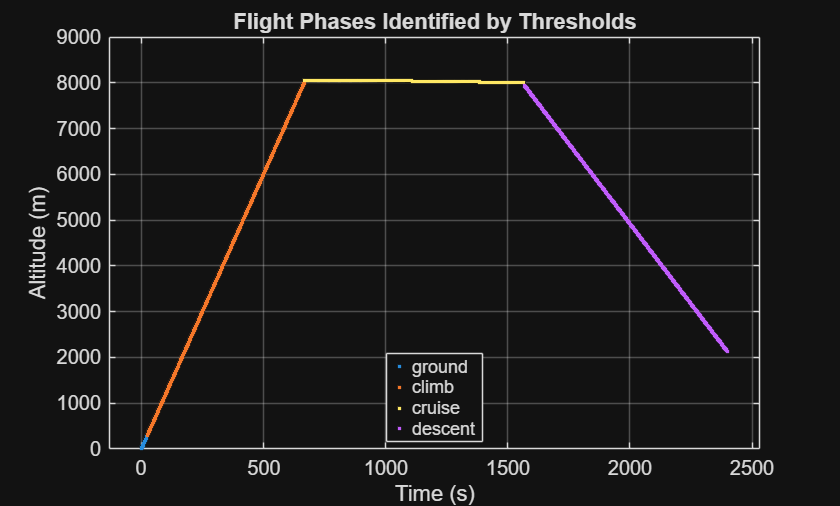


t       = data(:,1);
alt     = data(:,2);
speed   = data(:,3);

ALT_LOW = 300;       % below this = near ground
CLIMB_RATE = 3;      % >3 m/s = climbing
DESCENT_RATE = -3;   % <-3 m/s = descending
SPEED_TAKEOFF = 40;  % >40 m/s = airborne

phase = strings(length(t),1);

alt_rate = [0; diff(alt)];
CRUISE_RATE = 2;   % |alt_rate| <= 2 m/s = cruise


for i = 1:length(t)

    if alt(i) < ALT_LOW && speed(i) < 40
        phase(i) = "ground";

    elseif alt(i) < ALT_LOW && speed(i) >= 40
        phase(i) = "takeoff";

    elseif alt_rate(i) > CLIMB_RATE
        phase(i) = "climb";

    elseif abs(alt_rate(i)) <= CRUISE_RATE
        phase(i) = "cruise";

    elseif alt_rate(i) < DESCENT_RATE
        phase(i) = "descent";
    else
        phase(i) = "landing";
    end


end

plot(t, alt, 'k', 'LineWidth', 2)   % smooth altitude curve
hold on
gscatter(t, alt, phase)             % colored phase dots


gscatter(t, alt, phase)
xlabel('Time (s)')
ylabel('Altitude (m)')
title('Flight Phases Identified by Thresholds')
grid on